x = linspace(0, 20, 200)';
f = @(x) 3*x +2;
y = f(x) + 3.0*rand(size(x));

## Using 'fit' function

[f_fit, gof] = fit(x,y, 'poly1')

f_fit =      Linear model Poly1:
     f_fit(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       2.997  (2.977, 3.018)
       p2 =       3.501  (3.265, 3.737)

gof = struct with fields:
           sse: 142.9862
       rsquare: 0.9976
           dfe: 198
    adjrsquare: 0.9976
          rmse: 0.8498


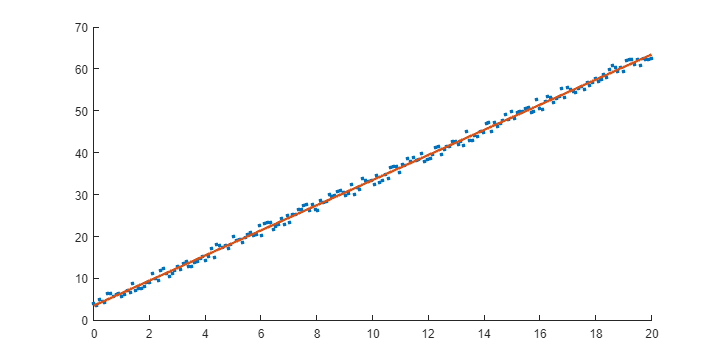


figure("Position",[0 0 800 400])
scatter(x,y, 10, 'o', 'filled')
hold on
plot(x,f_fit(x), 'LineWidth',2)

## Least Squres Approach

A = [x ones(size(x))];
b = y;

theta = A\b;